clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[2.626;6.924;24.665];
u31=[0.104;0.267;0.958];
r2=[2.440;11.449;17.249];
u32=[0.120;0.550;0.826];
r3=[7.518;0.711;21.079];
u33=[-0.104;0.267;-0.958];
r4=[7.512;7.189;13.247];
u34=[0.120;-0.550;-0.826];
r5=[2.446;5.502;9.417];
u35=[-0.104;-0.267;0.958];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];

hold on
axis([0 15 0 15]);
for R3=3:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     5.9000    3.0000    1.0016


ans =     5.2500    3.3000    1.0041


ans =     4.8500    3.6000    1.0054


ans =     4.6000    3.9000    1.0019


ans =     4.4000    4.2000    1.0053


ans =     4.2500    4.5000    1.0087


ans =     4.1500    4.8000    1.0057


ans =     4.0500    5.1000    1.0103


ans =     4.0000    5.4000    1.0018


ans =     3.9000    5.7000    1.0171


ans =     3.8500    6.0000    1.0159


ans =     3.8000    6.3000    1.0172


ans =     3.7500    6.6000    1.0206


ans =     3.7500    6.9000    1.0035


ans =     3.7000    7.2000    1.0095


ans =     3.6500    7.5000    1.0166


ans =     3.6500    7.8000    1.0019


ans =     3.6000    8.1000    1.0103


ans =     3.5500    8.4000    1.0193


ans =     3.5500    8.7000    1.0056


ans =     3.5000    9.0000    1.0151


ans =     3.5000    9.3000    1.0017


ans =     3.4500    9.6000    1.0113


ans =     3.4000    9.9000    1.0211


ans =     3.4000   10.2000    1.0076


ans =     3.3500   10.5000    1.0171


ans =     3.3500   10.8000    1.0035


ans =     3.3000   11.1000    1.0126


ans =     3.2500   11.4000    1.0216


ans =     3.2500   11.7000    1.0074


ans =     3.2000   12.0000    1.0157


ans =     3.2000   12.3000    1.0013


ans =     3.1500   12.6000    1.0090


ans =     3.1000   12.9000    1.0162


scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')

for R3=2:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     5.5000    2.0000    1.0045


ans =     5.1500    2.3000    1.0100


ans =     4.9000    2.6000    1.0132


ans =     4.7500    2.9000    1.0054


ans =     4.6000    3.2000    1.0120


ans =     4.5000    3.5000    1.0120


ans =     4.4500    3.8000    1.0010


ans =     4.3500    4.1000    1.0143


ans =     4.3000    4.4000    1.0124


ans =     4.2500    4.7000    1.0134


ans =     4.2000    5.0000    1.0166


ans =     4.2000    5.3000    1.0006


ans =     4.1500    5.6000    1.0065


ans =     4.1000    5.9000    1.0134


ans =     4.0500    6.2000    1.0213


ans =     4.0500    6.5000    1.0080


ans = 1×3
    4.0000    6.8000    1.0167


ans = 1×3
    4.0000    7.1000    1.0041


ans = 1×3
    3.9500    7.4000    1.0133


ans = 1×3
    3.9500    7.7000    1.0011


ans = 1×3
    3.9000    8.0000    1.0106


ans = 1×3
    3.8500    8.3000    1.0203


ans = 1×3
    3.8500    8.6000    1.0081


ans = 1×3
    3.8000    8.9000    1.0180


ans = 1×3
    3.8000    9.2000    1.0060


ans = 1×3
    3.7500    9.5000    1.0159


ans = 1×3
    3.7500    9.8000    1.0040


ans = 1×3
    3.7000   10.1000    1.0140


ans = 1×3
    3.7000   10.4000    1.0023


ans = 1×3
    3.6500   10.7000    1.0124


ans = 1×3
    3.6500   11.0000    1.0009


ans = 1×3
    3.6000   11.3000    1.0113


ans = 1×3
    3.5500   11.6000    1.0220


ans = 1×3
    3.5500   11.9000    1.0106


ans = 1×3
    3.5000   12.2000    1.0217


ans = 1×3
    3.5000   12.5000    1.0106


ans = 1×3
    3.4500   12.8000    1.0221


scatter(x2,y2,10,'markerfacecolor',[29, 50, 67]/256,...
        'markeredgecolor',[29, 50, 67]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','13')

for R3=2:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    7.5500    2.0000    1.0045


ans = 1×3
    7.3500    2.3000    1.0087


ans = 1×3
    7.2000    2.6000    1.0073


ans = 1×3
    7.0500    2.9000    1.0114


ans = 1×3
    6.9500    3.2000    1.0078


ans = 1×3
    6.8500    3.5000    1.0079


ans = 1×3
    6.7500    3.8000    1.0110


ans = 1×3
    6.7000    4.1000    1.0033


ans = 1×3
    6.6000    4.4000    1.0102


ans = 1×3
    6.5500    4.7000    1.0052


ans = 1×3
    6.5000    5.0000    1.0008


ans = 1×3
    6.4000    5.3000    1.0103


ans = 1×3
    6.3500    5.6000    1.0067


ans = 1×3
    6.3000    5.9000    1.0032


ans = 1×3
    6.2000    6.2000    1.0130


ans = 1×3
    6.1500    6.5000    1.0093


ans = 1×3
    6.1000    6.8000    1.0054


ans = 1×3
    6.0500    7.1000    1.0012


ans = 1×3
    5.9500    7.4000    1.0099


ans = 1×3
    5.9000    7.7000    1.0050


ans = 1×3
    5.8000    8.0000    1.0129


ans = 1×3
    5.7500    8.3000    1.0072


ans = 1×3
    5.7000    8.6000    1.0012


ans = 1×3
    5.6000    8.9000    1.0077


ans = 1×3
    5.5500    9.2000    1.0010


ans = 1×3
    5.4500    9.5000    1.0066


ans = 1×3
    5.3500    9.8000    1.0119


ans = 1×3
    5.3000   10.1000    1.0042


ans = 1×3
    5.2000   10.4000    1.0087


ans = 1×3
    5.1500   10.7000    1.0006


ans = 1×3
    5.0500   11.0000    1.0047


ans = 1×3
    4.9500   11.3000    1.0086


ans = 1×3
    4.9000   11.6000    1.0002


ans = 1×3
    4.8000   11.9000    1.0040


ans = 1×3
    4.7000   12.2000    1.0079


ans = 1×3
    4.6000   12.5000    1.0120


ans = 1×3
    4.5500   12.8000    1.0038


scatter(x3,y3,10,'markerfacecolor',[84, 130, 53]/256,...
        'markeredgecolor',[84, 130, 53]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','23')

for R3=3:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
    6.8500    3.0000    1.0006


ans = 1×3
    5.0500    3.3000    1.0027


ans = 1×3
    4.2500    3.6000    1.0036


ans = 1×3
    3.8000    3.9000    1.0085


ans = 1×3
    3.5500    4.2000    1.0040


ans = 1×3
    3.3500    4.5000    1.0097


ans = 1×3
    3.2000    4.8000    1.0168


ans = 1×3
    3.1000    5.1000    1.0167


ans = 1×3
    3.0500    5.4000    1.0028


ans = 1×3
    2.9500    5.7000    1.0190


ans = 1×3
    2.9000    6.0000    1.0163


ans = 1×3
    2.8500    6.3000    1.0176


ans = 1×3
    2.8000    6.6000    1.0221


ans = 1×3
    2.8000    6.9000    1.0012


ans = 1×3
    2.7500    7.2000    1.0099


ans = 1×3
    2.7000    7.5000    1.0207


ans = 1×3
    2.7000    7.8000    1.0034


ans = 1×3
    2.6500    8.1000    1.0166


ans = 1×3
    2.6500    8.4000    1.0008


ans = 1×3
    2.6000    8.7000    1.0155


ans = 1×3
    2.6000    9.0000    1.0005


ans = 1×3
    2.5500    9.3000    1.0163


ans = 1×3
    2.5500    9.6000    1.0018


ans = 1×3
    2.5000    9.9000    1.0183


ans = 1×3
    2.5000   10.2000    1.0040


ans = 1×3
    2.4500   10.5000    1.0207


ans = 1×3
    2.4500   10.8000    1.0064


ans = 1×3
    2.4000   11.1000    1.0232


ans = 1×3
    2.4000   11.4000    1.0088


ans = 1×3
    2.3500   11.7000    1.0255


ans = 1×3
    2.3500   12.0000    1.0109


ans = 1×3
    2.3000   12.3000    1.0272


ans = 1×3
    2.3000   12.6000    1.0124


ans = 1×3
    2.2500   12.9000    1.0283


scatter(x4,y4,10,'markerfacecolor',[63, 125, 162]/256,...
        'markeredgecolor',[63, 125, 162]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','24')

for R3=3:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r5,R1,R3,u32,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];   
end

ans = 1×3
    8.8500    3.0000    1.0039


ans = 1×3
    8.3500    3.3000    1.0013


ans = 1×3
    7.7500    3.6000    1.0059


ans = 1×3
    7.1500    3.9000    1.0036


ans = 1×3
    6.5000    4.2000    1.0022


ans = 1×3
    5.8000    4.5000    1.0039


ans = 1×3
    5.1500    4.8000    1.0016


ans = 1×3
    4.5500    5.1000    1.0015


ans = 1×3
    4.0500    5.4000    1.0011


ans = 1×3
    3.6000    5.7000    1.0089


ans = 1×3
    3.3000    6.0000    1.0022


ans = 1×3
    3.0000    6.3000    1.0059


ans = 1×3
    2.7500    6.6000    1.0064


ans = 1×3
    2.5500    6.9000    1.0001


ans = 1×3
    2.3000    7.2000    1.0122


ans = 1×3
    2.1000    7.5000    1.0147


ans = 1×3
    1.9500    7.8000    1.0054


ans = 1×3
    1.7500    8.1000    1.0152


ans = 1×3
    1.6000    8.4000    1.0127


ans = 1×3
    1.4500    8.7000    1.0149


ans = 1×3
    1.3500    9.0000    1.0037


ans = 1×3
    1.2000    9.3000    1.0213


ans = 1×3
    1.1500    9.6000    1.0009


ans = 1×3
    1.0500    9.9000    1.0171


ans = 1×3
    1.0000   10.2000    1.0136


ans = 1×3
    0.9500   10.5000    1.0198


ans = 1×3
    0.9000   10.8000    1.0374


ans = 1×3
    0.9000   11.1000    1.0083


ans = 1×3
    0.8500   11.4000    1.0423


ans = 1×3
    0.8500   11.7000    1.0183


ans = 1×3
    0.8000   12.0000    1.0703


ans = 1×3
    0.8000   12.3000    1.0502


ans = 1×3
    0.8000   12.6000    1.0317


ans = 1×3
    0.8000   12.9000    1.0146


scatter(x5,y5,10,'markerfacecolor',[239, 193, 48]/256,...
        'markeredgecolor',[239, 193, 48]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','25')

for R3=3:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r4,r5,R1,R3,u34,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];   
end

ans = 1×3
    3.3500    3.0000    1.0130


ans = 1×3
    3.2500    3.3000    1.0151


ans = 1×3
    3.2000    3.6000    1.0026


ans = 1×3
    3.1000    3.9000    1.0238


ans = 1×3
    3.0500    4.2000    1.0256


ans = 1×3
    3.0500    4.5000    1.0039


ans = 1×3
    3.0000    4.8000    1.0142


ans = 1×3
    2.9500    5.1000    1.0284


ans = 1×3
    2.9500    5.4000    1.0149


ans = 1×3
    2.9500    5.7000    1.0031


ans = 1×3
    2.9000    6.0000    1.0241


ans = 1×3
    2.9000    6.3000    1.0151


ans = 1×3
    2.9000    6.6000    1.0072


ans = 1×3
    2.9000    6.9000    1.0002


ans = 1×3
    2.8500    7.2000    1.0266


ans = 1×3
    2.8500    7.5000    1.0209


ans = 1×3
    2.8500    7.8000    1.0159


ans = 1×3
    2.8500    8.1000    1.0113


ans = 1×3
    2.8500    8.4000    1.0072


ans = 1×3
    2.8500    8.7000    1.0034


ans = 1×3
    2.8500    9.0000    1.0000


ans = 1×3
    2.8000    9.3000    1.0312


ans = 1×3
    2.8000    9.6000    1.0283


ans = 1×3
    2.8000    9.9000    1.0257


ans = 1×3
    2.8000   10.2000    1.0232


ans = 1×3
    2.8000   10.5000    1.0210


ans = 1×3
    2.8000   10.8000    1.0190


ans = 1×3
    2.8000   11.1000    1.0170


ans = 1×3
    2.8000   11.4000    1.0153


ans = 1×3
    2.8000   11.7000    1.0136


ans = 1×3
    2.8000   12.0000    1.0121


ans = 1×3
    2.8000   12.3000    1.0107


ans = 1×3
    2.8000   12.6000    1.0093


ans = 1×3
    2.8000   12.9000    1.0081


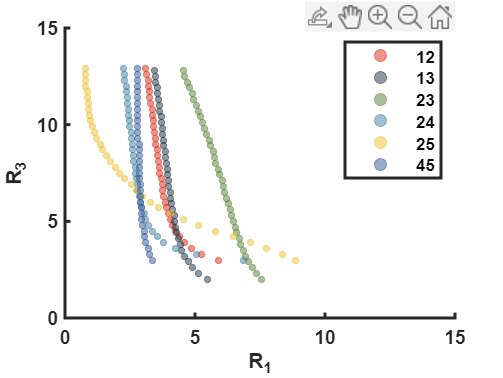

scatter(x6,y6,10,'markerfacecolor',[47, 85, 151]/256,...
        'markeredgecolor',[47, 85, 151]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','45')



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast');



hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
